clear

student_id = 5595738;
a = 5;
b = 9;
c = 8;

A = [0.3+a-b, 0.5-c;
     0, 1];
B = [0;1];

syms h
Fh = expm (A*h );
Gh = (Fh - eye (2) )/ A*B;

% Desired poles
p = [-1-2j, -1+2j];
K = place(A,B,p);

h_range = linspace(1e-4,1e0,1e5);
i = 1;
stable = zeros(size(h_range));
lm = zeros(size(h_range));

for h = h_range
    Fh = expm (A*h );
    Gh = (Fh - eye (2) )/ A*B;
    lm(i) = max(abs(eig(Fh-Gh*K)));
    if lm(i) < 1
        stable(i) = 1;
        h_max = h;
    end
    i = i+1;
end

h_max

h_max = 0.5118

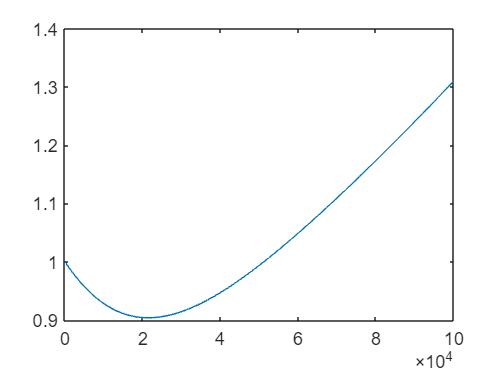

plot(lm)

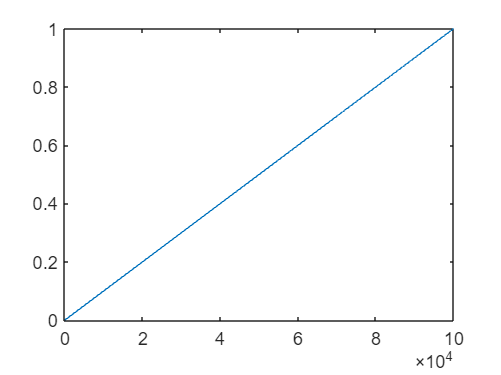

plot(h_range)